# Discrete-Time Signals: Operations, Manipulation and Audio Applications

**Digital Signal Processing – lecture live script.** This script walks through (almost) everything you can do to a discrete-time signal $x[n]$: generate it, scale it, shift it, fold it, resample it, add and multiply it, convolve it, correlate it, filter it and transform it. It ends by using exactly the same operations on real music: turning the volume up and down, slow motion, fast forward, pitch shifting, echo, reverb and more.

**How to use.** Run the script one section at a time (**Run Section**, Ctrl+Enter) with the output shown inline (View tab → Output Inline). It needs base MATLAB R2019b or newer (for `tiledlayout`); no toolbox is required. Every helper function is a local function in the last section of the script.

**Audio.** Turn your speakers on. Section 12 reuses the variables created in 12.1, so run 12.1 first. Each clip is announced with a short label and plays to the end before the next one starts.

## 0. Setup

Clear the workspace and set some plot defaults that make every figure in the script easier to read.

clear; clc; close all
set(groot, 'defaultAxesFontSize', 11, ...
           'defaultAxesXGrid', 'on', 'defaultAxesYGrid', 'on', ...
           'defaultLineLineWidth', 1.4);

## 1. What is a discrete-time signal?

A discrete-time signal is a sequence of numbers $x[n]$ defined only for integer $n$. It usually comes from sampling a continuous-time signal every $T_s = 1/F_s$ seconds:


$$x[n] = x_a(nT_s), \qquad T_s = \frac{1}{F_s}$$


**MATLAB pitfall:** MATLAB arrays start at index 1, but a signal may start at $n=-5$ or $n=0$. Whenever the index matters, store the index vector `n` next to the value vector `x` and always plot with `stem(n, x)`.

n = -5:10;                    % index vector: any integers, may be negative
x = 0.8.^n .* (n >= 0);       % x[n] = 0.8^n u[n]

table(n.', x.', 'VariableNames', {'n', 'x_n'})     % (index, value) pairs

figure
stem(n, x, 'filled'); xlabel('n'); ylabel('x[n]'); title('x[n] = 0.8^n u[n]')

Sampling a continuous signal: a 2 Hz cosine sampled at $F_s = 20$ Hz.

Fs = 20;  Ts = 1/Fs;                 % 20 samples per second
t  = 0:1e-3:1;                       % (almost) continuous time axis
xa = cos(2*pi*2*t);                  % analog signal: 2 Hz cosine
n  = 0:Fs;                           % sample indices covering one second
xn = cos(2*pi*2*n*Ts);               % x[n] = xa(n*Ts)

figure
plot(t, xa, 'Color', [0.7 0.7 0.7]); hold on
stem(n*Ts, xn, 'filled'); hold off
xlabel('t (s)'); legend('x_a(t)', 'x[n] = x_a(nT_s)'); title('Sampling a 2 Hz cosine at F_s = 20 Hz')

## 2. Generating elementary signals

Almost every signal can be built from a few building blocks. The most important one is the **unit impulse** $\delta[n]$, because any sequence is a weighted sum of shifted impulses:


$$x[n] = \sum_{k=-\infty}^{\infty} x[k]\,\delta[n-k]$$


rng(1)
n = -10:20;
u      = double(n >= 0);                              % unit step u[n]
delta  = double(n == 0);                              % unit impulse
ramp   = n .* u;                                      % unit ramp
decay  = 0.85.^n .* u;                                % decaying real exponential
grow   = 1.15.^n .* u;                                % growing real exponential
cplx   = exp((-0.08 + 1j*pi/6) * n) .* u;             % damped complex exponential
sine   = sin(2*pi*n/12);                              % sinusoid, period 12 samples
sq     = sign(sin(2*pi*n/12));                        % square wave
saw    = 2*mod(n/12, 1) - 1;                          % sawtooth
tri    = 2*abs(2*mod(n/12, 1) - 1) - 1;               % triangle wave
rectp  = double(abs(n) <= 3);                         % rectangular pulse
sinc_n = sincf(n/4);                                  % sampled sinc
chirp_n = sin(2*pi*(0.02*n + 0.003*n.^2)) .* u;       % linear chirp (frequency rises)
wn     = randn(size(n));                              % Gaussian white noise
un     = rand(size(n));                               % uniform white noise

sigs  = {delta, u, ramp, decay, grow, real(cplx), imag(cplx), sine, ...
         sq, saw, tri, rectp, sinc_n, chirp_n, wn, un};
names = {'\delta[n]', 'u[n]', 'ramp n u[n]', '0.85^n u[n]', '1.15^n u[n]', ...
         'Re of complex exp.', 'Im of complex exp.', 'sinusoid', ...
         'square wave', 'sawtooth', 'triangle', 'rectangular pulse', ...
         'sinc(n/4)', 'chirp', 'Gaussian noise', 'uniform noise'};

figure('Position', [100 100 1000 700])
tiledlayout(4, 4, 'TileSpacing', 'compact', 'Padding', 'compact')
for k = 1:numel(sigs)
    nexttile; stemplot(n, sigs{k}, names{k});
end

## 3. Amplitude (point-wise) operations

These operations act on each sample independently: $y[n] = f(x[n])$. They change the *height* of the signal, never its time axis. Multiplying two signals sample by sample is also point-wise, and it is the basis of modulation and windowing.

rng(1)
n = 0:39;
x = sin(2*pi*n/20);                              % test signal, period 20

ops = { x,                       'x[n]  (original)'; ...
        2*x,                     'amplify: 2x[n]'; ...
        0.5*x,                   'attenuate: 0.5x[n]'; ...
        -x,                      'invert: -x[n]'; ...
        x + 1,                   'DC offset: x[n]+1'; ...
        abs(x),                  'full-wave rectify: |x[n]|'; ...
        max(x, 0),               'half-wave rectify'; ...
        x.^2,                    'square: x[n]^2'; ...
        max(min(1.5*x,1),-1),    'hard clip: 1.5x[n] limited to +-1'; ...
        x .* cos(2*pi*n/4),      'modulate: x[n]cos(2\pi n/4)'; ...
        x + 0.5*sin(2*pi*n/5),   'add a 2nd sinusoid'; ...
        x + 0.2*randn(size(n)),  'add noise' };

figure('Position', [100 100 1000 650])
tiledlayout(3, 4, 'TileSpacing', 'compact', 'Padding', 'compact')
for k = 1:size(ops, 1)
    nexttile; stemplot(n, ops{k,1}, ops{k,2});
end

## 4. Operations on the time index

### 4.1 Shift, fold and scale: one idea, y[n] = x[g(n)]

Every operation on the independent variable is the same recipe: to get $y[n]$, look up $x$ at the index $g(n)$.

- Delay by $k$: $y[n] = x[n-k]$ (the graph moves right).

- Advance by $k$: $y[n] = x[n+k]$ (the graph moves left).

- Folding (time reversal): $y[n] = x[-n]$.

- Scaling: $y[n] = x[2n]$ (down-sampling) or $y[n] = x[n/2]$ (up-sampling, zeros where $n/2$ is not an integer).

**Order matters.** Fold-then-delay gives $x[2-n]$ but delay-then-fold gives $x[-n-2]$. The helper `xat(x, nx, q)` returns $x$ at the indices `q`, and zero outside the stored range.

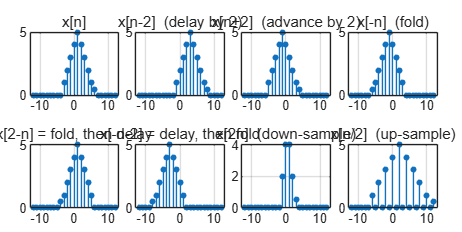

nx = -3:6;                                % indices of the stored samples
x  = [1 2 3 4 5 4 3 2 1 0.5];             % x[n] for n = -3..6
n  = -12:12;                              % common display axis

sigs = { xat(x,nx,n),      'x[n]'; ...
         xat(x,nx,n-2),    'x[n-2]  (delay by 2)'; ...
         xat(x,nx,n+2),    'x[n+2]  (advance by 2)'; ...
         xat(x,nx,-n),     'x[-n]  (fold)'; ...
         xat(x,nx,2-n),    'x[2-n] = fold, then delay'; ...
         xat(x,nx,-n-2),   'x[-n-2] = delay, then fold'; ...
         xat(x,nx,2*n),    'x[2n]  (down-sample)'; ...
         xat(x,nx,n/2),    'x[n/2]  (up-sample)' };

figure('Position', [100 100 1000 500])
tiledlayout(2, 4, 'TileSpacing', 'compact', 'Padding', 'compact')
for k = 1:size(sigs, 1)
    nexttile; stemplot(n, sigs{k,1}, sigs{k,2});
end

The same thing done by *index bookkeeping*: a delay only changes the labels of the samples, a fold reverses the samples and negates the labels. Both routes give identical results.

[xd, nd] = sigshift(x, nx, 2);            % same samples, index labels + 2
[xf, nf] = sigfold(x, nx);                % reversed samples, index labels negated

same_delay = isequal(xat(xd, nd, n), xat(x, nx, n-2))

same_delay = logical
   1


same_fold  = isequal(xat(xf, nf, n), xat(x, nx, -n))

same_fold = logical
   1


### 4.2 Adding and multiplying signals with different supports

Two sequences can only be added when they are aligned on a common index axis. Zero-padding both to the union of their supports does that.

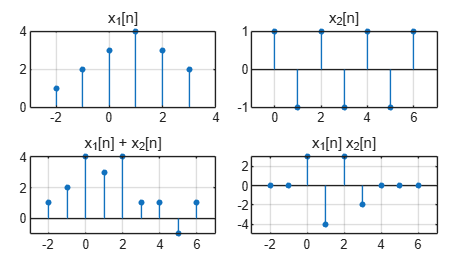

n1 = -2:3;   x1 = [1 2 3 4 3 2];
n2 =  0:6;   x2 = [1 -1 1 -1 1 -1 1];

[ys, ns] = sigadd(x1, n1, x2, n2);        % x1[n] + x2[n]
[yp, np] = sigmult(x1, n1, x2, n2);       % x1[n] * x2[n]

figure('Position', [100 100 900 500])
tiledlayout(2, 2, 'TileSpacing', 'compact', 'Padding', 'compact')
nexttile; stemplot(n1, x1, 'x_1[n]')
nexttile; stemplot(n2, x2, 'x_2[n]')
nexttile; stemplot(ns, ys, 'x_1[n] + x_2[n]')
nexttile; stemplot(np, yp, 'x_1[n] x_2[n]')

### 4.3 Down-sampling, up-sampling and interpolation

**Down-sampling** by $M$ keeps every $M$-th sample: $y[n] = x[Mn]$. **Up-sampling** by $L$ inserts $L-1$ zeros between samples. The zero-stuffed signal is then low-pass filtered (an *interpolation filter*) to fill in the gaps. Here the filter is a triangle, which gives linear interpolation.

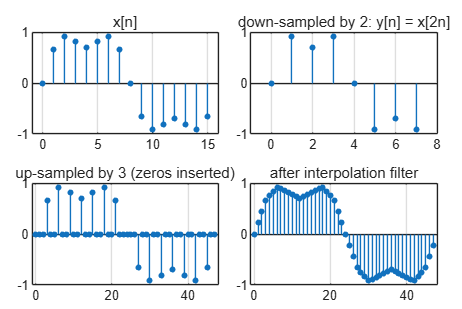

n = 0:15;
x = sin(2*pi*n/16) + 0.3*sin(2*pi*3*n/16);

M  = 2;  xd = x(1:M:end);                              % down-sample by 2: y[n] = x[2n]
L  = 3;  xu = zeros(1, L*numel(x));  xu(1:L:end) = x;  % up-sample by 3: insert zeros
h_lin = [1:L-1, L, L-1:-1:1] / L;                      % triangular kernel = linear interpolation
xi = conv(xu, h_lin, 'same');                          % interpolation = low-pass filtering

figure('Position', [100 100 900 600])
tiledlayout(2, 2, 'TileSpacing', 'compact', 'Padding', 'compact')
nexttile; stemplot(n, x, 'x[n]')
nexttile; stemplot(0:numel(xd)-1, xd, 'down-sampled by 2: y[n] = x[2n]')
nexttile; stemplot(0:numel(xu)-1, xu, 'up-sampled by 3 (zeros inserted)')
nexttile; stemplot(0:numel(xi)-1, xi, 'after interpolation filter')

Down-sampling without first removing the high frequencies causes **aliasing** (Section 10). Combining up-sampling by $L$ and down-sampling by $M$ changes the sample rate by the ratio $L/M$; we will use this for speed changes in Section 12.

## 5. Signal properties: symmetry, periodicity, energy and power

### 5.1 Even and odd parts

Every real signal splits uniquely into an even part and an odd part:


$$x_e[n] = \tfrac{1}{2}\big(x[n] + x[-n]\big), \qquad x_o[n] = \tfrac{1}{2}\big(x[n] - x[-n]\big)$$


n  = -15:15;
x  = 0.9.^n .* (n >= 0);                 % causal exponential: neither even nor odd
xr = fliplr(x);                          % x[-n]  (valid because n is symmetric about 0)
xe = (x + xr)/2;                         % even part
xo = (x - xr)/2;                         % odd part

checks = [isequal(xe, fliplr(xe)), isequal(xo, -fliplr(xo)), max(abs(x - (xe + xo))) < 1e-12]

checks = 1×3 logical array
   1   1   1


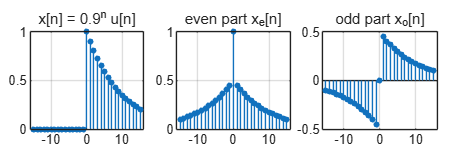


figure('Position', [100 100 900 300])
tiledlayout(1, 3, 'TileSpacing', 'compact', 'Padding', 'compact')
nexttile; stemplot(n, x,  'x[n] = 0.9^n u[n]')
nexttile; stemplot(n, xe, 'even part x_e[n]')
nexttile; stemplot(n, xo, 'odd part x_o[n]')

For complex signals the counterparts are the conjugate-symmetric and conjugate-antisymmetric parts, built with $x^*[-n]$.

rng(5)
z    = randn(size(n)) + 1j*randn(size(n));
zcs  = (z + conj(fliplr(z)))/2;                 % conjugate-symmetric part
zcas = (z - conj(fliplr(z)))/2;                 % conjugate-antisymmetric part
errors = [max(abs(zcs - conj(fliplr(zcs)))), max(abs(zcas + conj(fliplr(zcas)))), max(abs(z - zcs - zcas))]

errors = 1.0e-15 *

         0         0    0.1241


### 5.2 Periodicity

A discrete sinusoid $\cos(2\pi f_0 n)$ is periodic **only if **$f_0$** is a rational number** $f_0 = p/q$, and then the fundamental period is $q$. A sum of periodic signals is periodic with the least common multiple of the periods. Two more facts that have no analogue in continuous time: $\omega_0$ and $\omega_0 + 2\pi$ give exactly the same sequence.

n    = 0:59;
xp1  = cos(2*pi*(1/12)*n);              % f0 = 1/12   -> period 12
xp2  = cos(2*pi*(3/8)*n);               % f0 = 3/8    -> period 8
xsum = xp1 + xp2;                       % period lcm(12,8) = 24
xp3  = cos(2*pi*(1/sqrt(50))*n);        % f0 irrational -> NOT periodic

isPer = @(x, N) all(abs(x(1+N:end) - x(1:end-N)) < 1e-9);
findN = @(x) find(arrayfun(@(N) isPer(x, N), 1:40), 1);     % smallest period up to 40 (empty = none)

N1   = findN(xp1)

N1 = 12

N2   = findN(xp2)

N2 = 8

Nsum = findN(xsum)

Nsum = 24

N3   = findN(xp3)                        % empty: not periodic


N3 =

  1×0 empty double row vector




alias_error = max(abs(cos(0.3*pi*n) - cos((0.3*pi + 2*pi)*n)))     % identical sequences

alias_error = 3.2338e-14

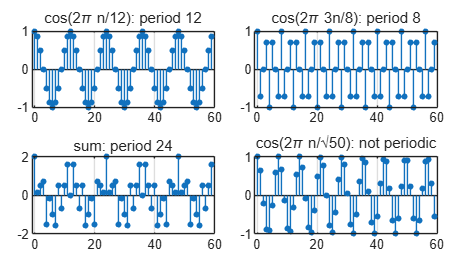


figure('Position', [100 100 900 500])
tiledlayout(2, 2, 'TileSpacing', 'compact', 'Padding', 'compact')
nexttile; stemplot(n, xp1,  'cos(2\pi n/12): period 12')
nexttile; stemplot(n, xp2,  'cos(2\pi 3n/8): period 8')
nexttile; stemplot(n, xsum, 'sum: period 24')
nexttile; stemplot(n, xp3,  'cos(2\pi n/\surd50): not periodic')

### 5.3 Energy, power and statistics

Energy $E = \sum |x[n]|^2$ is finite for decaying (transient) signals. Periodic and random signals have infinite energy but finite average power $P = \lim \frac{1}{N}\sum |x[n]|^2$. In audio, RMS level and crest factor are what people call *loudness* and *dynamics*.

rng(3)
% Energy signal: 0.95^n u[n]
k = 0:999;
E_num = sum((0.95.^k).^2);   E_theory = 1/(1 - 0.95^2);
fprintf('Energy of 0.95^n u[n]: numerical = %.4f, theory = %.4f\n', E_num, E_theory);

Energy of 0.95^n u[n]: numerical = 10.2564, theory = 10.2564



% Power signal: noisy sinusoid
n = 0:199;
s = 3*cos(2*pi*n/20);              % 10 whole periods, power A^2/2 = 4.5
v = 0.5*randn(size(n));            % noise, power 0.25
x = s + v;
P = mean(abs(x).^2);               % average power

Metrics = table(mean(x), sqrt(P), max(abs(x)), max(abs(x))/sqrt(P), 10*log10(P), ...
    'VariableNames', {'Mean', 'RMS', 'Peak', 'CrestFactor', 'Power_dB'})

Metrics = 1×5 table
      Mean        RMS       Peak     CrestFactor    Power_dB
    _________    ______    ______    ___________    ________

    0.0037738    2.1694    3.9811      1.8351        6.7268 


SNR_dB = 12.7741

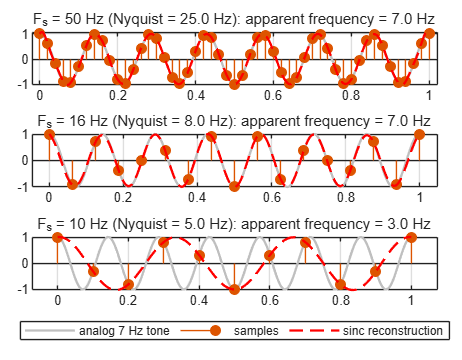

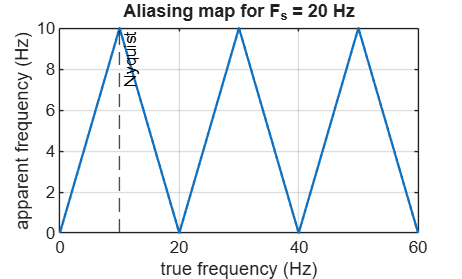

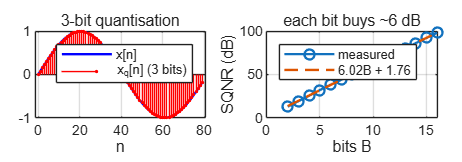


SNR_dB = 10*log10(mean(s.^2) / mean(v.^2))       % signal-to-noise ratio

## 12. Application: processing real music

Music is just a long discrete-time signal: The mp3 file is typically sampled with 44.1 kHz sampling frequency. Every operation in the previous sections applies directly. Below, each classic audio effect is shown next to the DSP idea it really is.

### 12.1 Load the music and look at it

**Run this section first.** To use your own song instead, uncomment the `audioread` lines. The signal is normalised to a peak of 0.5 (−6 dBFS) so that gain experiments have headroom before clipping at ±1.

% x = y(:);                            % column vector
% x = x(1:min(end, 6*Fs));             % keep the first 6 seconds
% x = 0.5 * x / max(abs(x));           % normalise: peak = 0.5 (-6 dBFS)

% ---- to use your own music, uncomment these lines ----
[x, Fs] = audioread('Justin Bieber - Ghost.mp3');   x = mean(x, 2);        % stereo -> mono
x = x(1:min(end, 8*Fs));   x = 0.5 * x / max(abs(x));

N = numel(x);   t = (0:N-1).' / Fs;
fprintf('Fs = %d Hz | duration = %.2f s | %d samples | peak = %.2f | RMS = %.1f dBFS\n', ...
        Fs, N/Fs, N, max(abs(x)), 20*log10(sqrt(mean(x.^2))));

Fs = 44100 Hz | duration = 8.00 s | 352800 samples | peak = 0.50 | RMS = -16.7 dBFS



setappdata(0, 'hearWait', true);     % true: wait for each clip to finish; false: return immediately
hear(x, Fs, 'Original');

Original


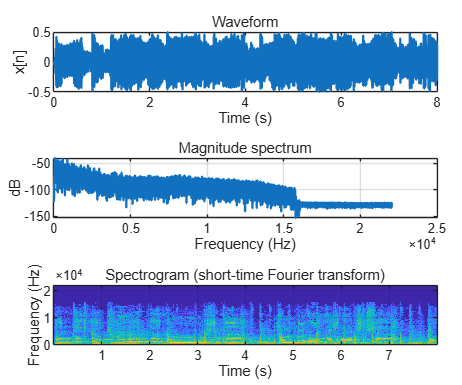


Nh = floor(N/2);   f = (0:Nh-1) * Fs/N;   X = fft(x);
figure('Position', [100 100 900 750])
tiledlayout(3, 1, 'TileSpacing', 'compact', 'Padding', 'compact')
nexttile; plot(t, x); xlabel('Time (s)'); ylabel('x[n]'); title('Waveform', 'FontWeight', 'normal')
nexttile; plot(f, 20*log10(abs(X(1:Nh))/N + 1e-9)); xlabel('Frequency (Hz)'); ylabel('dB'); title('Magnitude spectrum', 'FontWeight', 'normal')
nexttile; plotspec(x, Fs, 'Spectrogram (short-time Fourier transform)')

### 12.2 Volume: turning it up and down

Volume is multiplication by a constant, $y[n] = g\,x[n]$. Loudness is perceived roughly logarithmically, so gain is quoted in decibels: $g = 10^{G_{dB}/20}$. **+6 dB doubles the amplitude, −6 dB halves it, −20 dB is a factor of 10.**

dB = [-40 -20 -12 -6 -3 0 3 6 12 20].';
table(dB, 10.^(dB/20), 'VariableNames', {'Gain_dB', 'Factor'})

ans = 10×2 table
    Gain_dB    Factor 
    _______    _______

      -40         0.01
      -20          0.1
      -12      0.25119
       -6      0.50119
       -3      0.70795
        0            1
        3       1.4125
        6       1.9953
       12       3.9811
       20           10


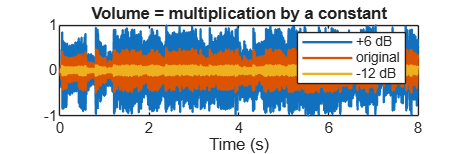


x_up   = 10^(  6/20) * x;            % +6 dB  : amplitude x 2    (peak 0.5 -> 1.0)
x_down = 10^(-12/20) * x;            % -12 dB : amplitude x 0.25

figure('Position', [100 100 900 300])
plot(t, x_up, t, x, t, x_down); xlabel('Time (s)'); legend('+6 dB', 'original', '-12 dB'); title('Volume = multiplication by a constant')


hear(x,      Fs, 'Original');

Original


hear(x_up,   Fs, '+6 dB (louder)');

+6 dB (louder)


hear(x_down, Fs, '-12 dB (quieter)');

-12 dB (quieter)


**Too much gain: clipping.** A DAC cannot output more than ±1. Samples beyond full scale are flattened (hard clipping), which creates harmonic distortion. A smooth saturation such as `tanh` bends the peaks instead of chopping them, which sounds gentler.

x_big  = 10^(20/20) * x;                    % +12 dB: the peak would be about 2.0
x_hard = max(min(x_big, 1), -1);            % hard clipping at +-1
x_soft = tanh(x_big);                       % soft saturation
fprintf('peak before clipping = %.2f, samples clipped: %.1f %%\n', max(abs(x_big)), 100*mean(abs(x_big) > 1));

peak before clipping = 5.00, samples clipped: 48.3 %


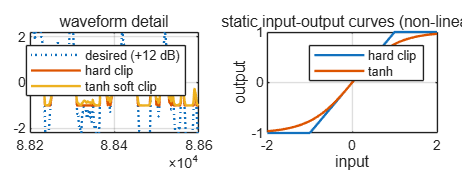


seg = round(2*Fs) + (1:400);                % a short piece of the waveform
figure('Position', [100 100 900 350])
tiledlayout(1, 2, 'TileSpacing', 'compact', 'Padding', 'compact')
nexttile; plot(seg, x_big(seg), ':', seg, x_hard(seg), seg, x_soft(seg)); ylim([-2.2 2.2])
legend('desired (+12 dB)', 'hard clip', 'tanh soft clip'); title('waveform detail', 'FontWeight', 'normal')
nexttile; v = linspace(-2, 2, 401); plot(v, max(min(v,1),-1), v, tanh(v)); grid on
xlabel('input'); ylabel('output'); title('static input-output curves (non-linear!)', 'FontWeight', 'normal'); legend('hard clip', 'tanh')


hear(x_hard, Fs, '+12 dB with hard clipping (harsh)');

+12 dB with hard clipping (harsh)


hear(x_soft, Fs, '+12 dB with soft saturation');

+12 dB with soft saturation


### 12.3 Fade in/out, normalisation and compression

A **fade** is multiplication by a slowly varying gain $g[n]$ (an envelope). **Normalisation** picks one constant gain to hit a target peak or RMS level. A **compressor** is a non-linear gain: levels above a threshold are reduced by a ratio, and then make-up gain brings the whole signal back up, so quiet parts become louder without clipping.

% Linear fade-in and fade-out (1 s each)
nf  = round(1*Fs);
env = ones(N, 1);
env(1:nf)         = linspace(0, 1, nf).';
env(end-nf+1:end) = linspace(1, 0, nf).';
x_fade = x .* env;

% Peak and RMS normalisation
x_peak = 0.99 * x / max(abs(x));                         % peak -> just below full scale
x_rms  = 10^(-20/20) / sqrt(mean(x.^2)) * x;             % RMS  -> -20 dBFS

% Static compressor + make-up gain
thr = 0.2;   ratio = 4;
comp   = @(v) sign(v) .* (min(abs(v), thr) + max(abs(v) - thr, 0)/ratio);
x_comp = comp(x);
x_comp = x_comp * (max(abs(x)) / max(abs(x_comp)));      % make-up gain restores the original peak
fprintf('RMS: original %.1f dBFS -> compressed %.1f dBFS (same peak)\n', ...
        20*log10(sqrt(mean(x.^2))), 20*log10(sqrt(mean(x_comp.^2))));

RMS: original -16.7 dBFS -> compressed -12.6 dBFS (same peak)


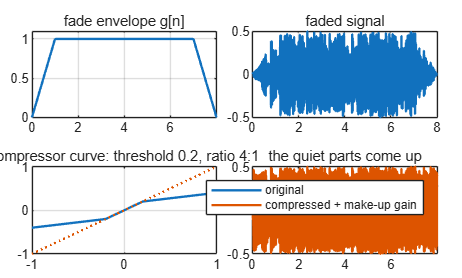


figure('Position', [100 100 1000 600])
tiledlayout(2, 2, 'TileSpacing', 'compact', 'Padding', 'compact')
nexttile; plot(t, env); ylim([0 1.1]); title('fade envelope g[n]', 'FontWeight', 'normal')
nexttile; plot(t, x_fade); title('faded signal', 'FontWeight', 'normal')
nexttile; v = linspace(-1, 1, 401); plot(v, comp(v), v, v, ':'); grid on; title('compressor curve: threshold 0.2, ratio 4:1', 'FontWeight', 'normal')
nexttile; plot(t, x, t, x_comp); legend('original', 'compressed + make-up gain'); title('the quiet parts come up', 'FontWeight', 'normal')


hear(x_fade, Fs, 'fade in / fade out');

fade in / fade out


hear(x_comp, Fs, 'compressed (louder quiet parts, same peak)');

compressed (louder quiet parts, same peak)


### 12.4 Speed: faster and slow motion (tape-style)

**Idea 1: change the playback clock.** Play the *same samples* at a different rate. Twice the rate is twice as fast and one octave higher; half the rate is slow motion and one octave lower. This is exactly what a vinyl record or a tape machine does.

hear(x, Fs,     'Original');

Original


hear(x, 1.5*Fs, 'played at 1.5 Fs: 1.5x faster AND higher pitch');

played at 1.5 Fs: 1.5x faster AND higher pitch


hear(x, 0.6*Fs, 'played at 0.6 Fs: slow motion AND lower pitch');

played at 0.6 Fs: slow motion AND lower pitch


**Idea 2: change the data.** To get the same effect at the normal sample rate, read the signal at fractional positions $1, 1+r, 1+2r, \dots$ and interpolate. This is $y[n] = x(rn)$, the general time-scaling of Section 4.1. For $r>1$ (speed-up) we must first low-pass filter, otherwise frequencies above $F_s/(2r)$ alias (Section 10.1).

y_fast = change_speed(x, 1.5);            % read positions 1, 2.5, 4, ...
y_slow = change_speed(x, 0.6);            % read positions 1, 1.6, 2.2, ...
fprintf('durations: original %.2f s | fast %.2f s | slow %.2f s\n', N/Fs, numel(y_fast)/Fs, numel(y_slow)/Fs);

durations: original 8.00 s | fast 5.33 s | slow 13.33 s


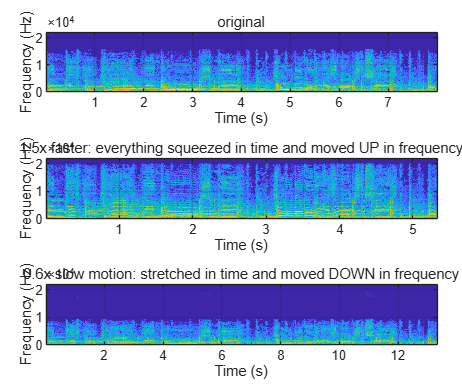


figure('Position', [100 100 900 750])
tiledlayout(3, 1, 'TileSpacing', 'compact', 'Padding', 'compact')
nexttile; plotspec(x,      Fs, 'original')
nexttile; plotspec(y_fast, Fs, '1.5x faster: everything squeezed in time and moved UP in frequency')
nexttile; plotspec(y_slow, Fs, '0.6x slow motion: stretched in time and moved DOWN in frequency')


hear(y_fast, Fs, 'resampled 1.5x faster');

resampled 1.5x faster


hear(y_slow, Fs, 'resampled 0.6x (slow motion)');

resampled 0.6x (slow motion)


**Why the anti-alias filter matters.** Same 2x speed-up, with and without the low-pass filter. Without it, the components between 2 and 4 kHz fold back into the audible band as inharmonic garbage.

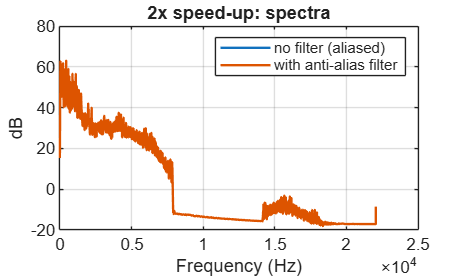

y2_alias = change_speed(x, 2, false);     % no anti-alias filter
y2_clean = change_speed(x, 2, true);      % with anti-alias filter

L2 = numel(y2_alias);  Lh = floor(L2/2);  fa = (0:Lh-1) * Fs/L2;
sm  = @(v) conv(20*log10(abs(v(1:Lh)) + 1e-9), ones(64,1)/64, 'same');    % smoothed spectrum in dB
figure
plot(fa, sm(fft(y2_alias)), fa, sm(fft(y2_clean)));
xlabel('Frequency (Hz)'); ylabel('dB'); legend('no filter (aliased)', 'with anti-alias filter'); title('2x speed-up: spectra')


hear(y2_alias, Fs, '2x faster, NO anti-alias filter');

2x faster, NO anti-alias filter


hear(y2_clean, Fs, '2x faster, with anti-alias filter');

2x faster, with anti-alias filter


**Idea 3: rational sample-rate conversion.** Up-sample by $L$, low-pass filter, down-sample by $M$. The signal now has $L/M$ times as many samples, so playing it at $F_s$ changes the speed by the factor $M/L$. This is the integer-arithmetic version of the same operation (Section 4.3).

y_23 = resamp_LM(x, 2, 3);                % L/M = 2/3 : 2/3 as many samples -> 1.5x faster
y_43 = resamp_LM(x, 4, 3);                % L/M = 4/3 : 4/3 as many samples -> 0.75x speed (slower)
fprintf('durations: original %.2f s | L/M=2/3 %.2f s | L/M=4/3 %.2f s\n', N/Fs, numel(y_23)/Fs, numel(y_43)/Fs);

durations: original 8.00 s | L/M=2/3 5.33 s | L/M=4/3 10.67 s



hear(y_23, Fs, 'L/M = 2/3 : 1.5x faster');

L/M = 2/3 : 1.5x faster


hear(y_43, Fs, 'L/M = 4/3 : 0.75x speed');

L/M = 4/3 : 0.75x speed


### 12.5 Speed without changing the pitch (time-stretching)

Tape-style speed change couples tempo and pitch. To change **tempo only**, use WSOLA (Waveform-Similarity Overlap-Add):

- Cut the signal into overlapping Hann-windowed frames of about 60 ms.

- Take input frames at a hop $H_a = \text{rate}\cdot H_s$, but write them to the output with a fixed hop $H_s$. This changes the tempo.

- Nudge each input frame by a few samples so that it best matches (maximum normalised cross-correlation) the natural continuation of the previous frame. This keeps the waveforms in phase and avoids warbling.

- Overlap-add the frames.

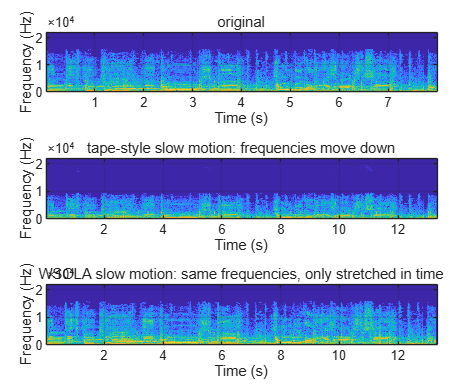

y_fast_p = wsola(x, Fs, 1.5);             % 1.5x faster, same pitch
y_slow_p = wsola(x, Fs, 0.6);             % 0.6x slower, same pitch
y_slow_t = change_speed(x, 0.6);          % tape-style slow motion, for comparison

figure('Position', [100 100 900 750])
tiledlayout(3, 1, 'TileSpacing', 'compact', 'Padding', 'compact')
nexttile; plotspec(x,        Fs, 'original')
nexttile; plotspec(y_slow_t, Fs, 'tape-style slow motion: frequencies move down')
nexttile; plotspec(y_slow_p, Fs, 'WSOLA slow motion: same frequencies, only stretched in time')


hear(x,        Fs, 'Original');

Original


hear(y_slow_p, Fs, 'WSOLA 0.6x: slow motion, pitch unchanged');

WSOLA 0.6x: slow motion, pitch unchanged


hear(y_fast_p, Fs, 'WSOLA 1.5x: faster, pitch unchanged');

WSOLA 1.5x: faster, pitch unchanged


### 12.6 Pitch shifting

Pitch shifting is the mirror image: change the pitch and keep the duration. **Time-stretch by **$\rho$** (pitch unchanged), then speed up by **$\rho$** (tape-style)**. The pitch goes up by $\rho$ and the duration returns to the original. For $k$ semitones, $\rho = 2^{k/12}$.

semitones = [-12 -7 -5 -2 2 4 5 7 12].';
table(semitones, 2.^(semitones/12), 'VariableNames', {'Semitones', 'FrequencyRatio'})

ans = 9×2 table
    Semitones    FrequencyRatio
    _________    ______________

       -12              0.5    
        -7          0.66742    
        -5          0.74915    
        -2           0.8909    
         2           1.1225    
         4           1.2599    
         5           1.3348    
         7           1.4983    
        12                2    


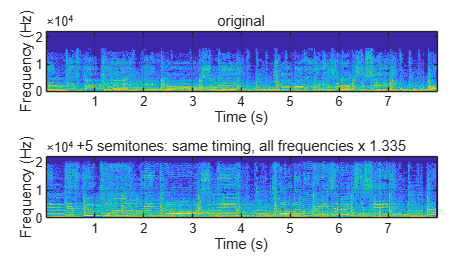


x_pitch_up   = pitch_shift(x, Fs, +10);                  % up a perfect fourth, same duration
x_pitch_down = pitch_shift(x, Fs, -5);                  % down a perfect fourth
x_harmony    = nrm(x + pitch_shift(x, Fs, +7));         % add a voice a major third above

figure('Position', [100 100 900 500])
tiledlayout(2, 1, 'TileSpacing', 'compact', 'Padding', 'compact')
nexttile; plotspec(x,            Fs, 'original')
nexttile; plotspec(x_pitch_up,   Fs, '+5 semitones: same timing, all frequencies x 1.335')


hear(x_pitch_up,   Fs, '+5 semitones');

+5 semitones


hear(x_pitch_down, Fs, '-5 semitones');

-5 semitones


hear(x_harmony,    Fs, 'original + major-third harmony');

original + major-third harmony


### 12.7 Time-varying speed: tape stop and vibrato

Generalise time scaling to $y[n] = x(\tau[n])$ where the read position $\tau[n]$ is any increasing curve. A constant slope gives a speed change, a slope that decays to zero gives the **tape-stop** effect and a wobbling position gives **vibrato**. The read position is the running sum of the speed: $\tau[n] = 1 + \sum_{k<n} s[k]$.

% Tape stop: speed 1 -> 0.02 during the last 2 seconds
s  = ones(N, 1);
i0 = N - round(2*Fs);
s(i0:end) = linspace(1, 0.02, N - i0 + 1).';
tau = 1 + [0; cumsum(s(1:end-1))];                  % read position (in samples)
x_stop = interp1((1:N).', x, tau, 'linear', 0);

% Vibrato: read position wobbles +-2 ms at 5 Hz
depth = round(0.002*Fs);
tau_v = (1:N).' + depth*sin(2*pi*5*t);
x_vib = interp1((1:N).', x, tau_v, 'linear', 0);

figure('Position', [100 100 900 350])
tiledlayout(1, 2, 'TileSpacing', 'compact', 'Padding', 'compact')
nexttile; yyaxis left; plot(t, s); ylabel('speed s[n]'); yyaxis right; plot(t, tau); ylabel('read position \tau[n]'); xlabel('Time (s)'); title('tape stop', 'FontWeight', 'normal')
nexttile; plot(t(1:Fs), tau_v(1:Fs) - (1:Fs).'); xlabel('Time (s)'); ylabel('\tau[n] - n'); title('vibrato: position wobble', 'FontWeight', 'normal')

hear(x_stop, Fs, 'tape stop');
hear(x_vib,  Fs, 'vibrato');

## Local functions

Helper functions used throughout the script. In a live script, local functions must be at the end of the file. Nothing here needs a toolbox.

function y = sincf(x)
    % normalised sinc, sin(pi x)/(pi x), with sinc(0) = 1
    y = ones(size(x));
    k = x ~= 0;
    y(k) = sin(pi*x(k)) ./ (pi*x(k));
end

function stemplot(n, x, ttl)
    % stem plot with a small title, used inside tiledlayout
    stem(n, x, 'filled', 'MarkerSize', 3);
    title(ttl, 'FontWeight', 'normal', 'FontSize', 9);
    xlim([min(n)-1, max(n)+1]);
end

function s = ternary(c, a, b)
    if c
        s = a;
    else
        s = b;
    end
end

function y = xat(x, nx, q)
    % value of the sequence x (stored on the index vector nx) at the indices q; zero elsewhere
    y = zeros(size(q));
    [tf, loc] = ismember(q, nx);
    y(tf) = x(loc(tf));
end

function [y, ny] = sigshift(x, nx, k)
    % y[n] = x[n-k]: same samples, new index labels
    y = x;  ny = nx + k;
end

function [y, ny] = sigfold(x, nx)
    % y[n] = x[-n]: reversed samples, negated index labels
    y = fliplr(x);  ny = -fliplr(nx);
end

function [y, n] = sigadd(x1, n1, x2, n2)
    n = min([n1 n2]) : max([n1 n2]);
    y = xat(x1, n1, n) + xat(x2, n2, n);
end

function [y, n] = sigmult(x1, n1, x2, n2)
    n = min([n1 n2]) : max([n1 n2]);
    y = xat(x1, n1, n) .* xat(x2, n2, n);
end

function [y, ny] = conv_n(x, nx, h, nh)
    % convolution with index vector
    y  = conv(x, h);
    ny = (nx(1) + nh(1)) : (nx(end) + nh(end));
end

function [r, lags] = xcorr_n(x, y)
    % cross-correlation r_xy[m] = sum_n x[n+m] conj(y[n]), lags -(Ny-1) ... Nx-1
    x = x(:).';  y = y(:).';
    r    = conv(x, conj(fliplr(y)));
    lags = -(numel(y)-1) : (numel(x)-1);
end

function y = medfilt_n(x, M)
    % median filter, odd window length M, edges padded by repetition
    pad = floor(M/2);
    xp  = [repmat(x(1), 1, pad), x, repmat(x(end), 1, pad)];
    y   = zeros(size(x));
    for i = 1:numel(x)
        y(i) = median(xp(i:i+M-1));
    end
end

function H = freqz_n(b, a, w)
    % frequency response B(e^jw)/A(e^jw) at the frequencies w (rad/sample)
    b = b(:).';  a = a(:).';  w = w(:).';
    H = (b * exp(-1j*(0:numel(b)-1).'*w)) ./ (a * exp(-1j*(0:numel(a)-1).'*w));
end

function h = lowpass_fir(fc, N)
    % windowed-sinc low-pass. fc = cut-off in cycles/sample (0..0.5), N = odd number of taps
    m = 0:N-1;
    h = 2*fc*sincf(2*fc*(m - (N-1)/2));           % ideal low-pass impulse response, delayed to be causal
    h = h .* (0.54 - 0.46*cos(2*pi*m/(N-1)));     % Hamming window
    h = h / sum(h);                               % unity gain at DC
end

function y = fir_apply(x, h)
    % zero-phase-aligned FIR filtering that always returns a column
    y = conv(x(:), h(:), 'same');
end

function xq = quantize(x, B)
    % B-bit mid-rise uniform quantiser for -1 <= x < 1
    xq = (floor(x * 2^(B-1)) + 0.5) / 2^(B-1);
end

function y = nrm(x)
    % scale to a peak of 0.7
    y = 0.7 * x / max(abs(x(:)));
end

function hear(x, Fs, label)
    % announce and play a clip; optionally wait until it has finished
    if nargin > 2, fprintf('%s\n', label); end
    sound(x, Fs);
    if getappdata(0, 'hearWait')
        pause(size(x, 1)/Fs + 0.3);
    end
end

function plotspec(x, Fs, ttl)
    % spectrogram (short-time Fourier transform) without any toolbox
    Nw = 512;  hop = 128;
    w  = 0.5 - 0.5*cos(2*pi*(0:Nw-1).'/Nw);
    x  = x(:);
    nF = floor((numel(x) - Nw)/hop) + 1;
    S  = zeros(Nw/2 + 1, nF);
    for m = 1:nF
        seg    = x((m-1)*hop + (1:Nw)) .* w;
        Xs     = fft(seg);
        S(:,m) = abs(Xs(1:Nw/2+1));
    end
    tS  = ((0:nF-1)*hop + Nw/2) / Fs;
    fS  = (0:Nw/2) * Fs / Nw;
    SdB = 20*log10(S + 1e-6);
    SdB = max(SdB, max(SdB(:)) - 70);             % show a 70 dB dynamic range
    imagesc(tS, fS, SdB);  axis xy
    xlabel('Time (s)');  ylabel('Frequency (Hz)');  title(ttl, 'FontWeight', 'normal');
end

function y = change_speed(x, r, antialias)
    % speed change by resampling: y[n] = x(r n). r > 1 faster/higher pitch, r < 1 slower/lower pitch
    if nargin < 3, antialias = true; end
    x = x(:);  N = numel(x);
    if r > 1 && antialias
        x = conv(x, lowpass_fir(0.45/r, 121).', 'same');     % remove what would fold back
    end
    pos = (1:r:N).';                                          % fractional read positions
    y   = interp1((1:N).', x, pos, 'spline');
end

function y = resamp_LM(x, L, M)
    % rational sample-rate conversion by L/M: up-sample, low-pass, down-sample
    x  = x(:);
    xu = zeros(L*numel(x), 1);  xu(1:L:end) = x;              % expander
    fc = 0.45 / max(L, M);
    h  = L * lowpass_fir(fc, 20*max(L, M) + 1);               % gain L compensates the zero insertion
    v  = conv(xu, h(:), 'same');
    y  = v(1:M:end);                                          % compressor
end

function y = wsola(x, Fs, rate)
    % Waveform-Similarity Overlap-Add time-scale modification (pitch preserved).
    % rate > 1: faster (shorter),  rate < 1: slower (longer)
    x    = x(:);  N = numel(x);
    Nw   = 2*round(0.03*Fs);                                  % frame length (~60 ms), even
    Hs   = Nw/2;                                              % synthesis hop (50 % overlap)
    Dmax = round(Hs/2);                                       % search tolerance +/- samples
    win  = 0.5 - 0.5*cos(2*pi*(0:Nw-1).'/Nw);                 % periodic Hann: overlapped copies add to 1
    nFr  = floor((N/rate - Nw)/Hs) + 1;
    xp   = [x; zeros(2*Nw + 2*Dmax, 1)];
    y    = zeros(nFr*Hs + Nw, 1);
    w0   = win;  w0(1:Hs) = 1;                                % no fade-in on the very first half frame
    y(1:Nw) = w0 .* xp(1:Nw);
    prev = 0;                                                 % start (0-based) of the previously used frame
    for m = 1:nFr-1
        target = round(m*Hs*rate);                            % nominal analysis position
        ref    = xp(prev + Hs + (1:Nw));                      % what would naturally follow the last frame
        nref   = norm(ref);
        best   = -inf;  pos = target;
        for cand = max(target - Dmax, 0) : target + Dmax
            seg = xp(cand + (1:Nw));
            c   = (seg.' * ref) / (norm(seg)*nref + eps);     % normalised cross-correlation
            if c > best, best = c; pos = cand; end
        end
        idx    = m*Hs + (1:Nw);
        y(idx) = y(idx) + win .* xp(pos + (1:Nw));
        prev   = pos;
    end
    y = y(1:min(numel(y), round(N/rate)));
end

function y = pitch_shift(x, Fs, semitones)
    % change pitch, keep duration: time-stretch by rho, then speed up by rho
    rho = 2^(semitones/12);
    y   = wsola(x, Fs, 1/rho);
    y   = change_speed(y, rho);
    N   = numel(x);
    if numel(y) < N, y(end+1:N, 1) = 0; end
    y   = y(1:N);
end